clear; clc;

%% [1] 설정
csv_path = 'D:\W00Y0NG\PRGM2\2025BCI\archive\Data\BrainFlow-RAW_2025-03-20_17-42-00_0.csv';
epoch_table_path = 'D:\W00Y0NG\PRGM2\2025BCI\archive\Video\experiment_epochs5.xlsx';
loc_path = 'D:\W00Y0NG\PRGM2\MATLAB\eeglab2024.2\sample_locs\Standard-10-20-Cap81.ced';
save_filename = 'subject1_cleaned.set';
fs = 125;

selected_labels = {'FP1','FP2','C3','C4','P7','P8','O1','O2', ...
                   'F7','F8','F3','F4','T7','T8','P3','P4'};

%% [2] CSV + 자극 → epoch 데이터 생성
[epochedEEG, labels] = epochEEGfromCSV(csv_path, epoch_table_path, fs, 10);


%% [3] epoch 데이터 → EEGLAB EEG 구조체
EEG = createEEGLABStruct(epochedEEG, labels, fs, loc_path, selected_labels, '');

Reading file (lines): 10 20 30 40 50 60 70 80 81
readlocs() warning: Fewer columns in the input than expected.
                    See >> help readlocs
Saving dataset...



%% [4] EEG 구조체 → 전처리 클래스 생성
p = EEGPreprocessor(EEG, labels, EEG.chanlocs);

%% [5] 전처리 단계 실행
p = p.applyBandpass(0.5, 40);

Bandpass filtering complete.


p = p.applyNotch(50);

Notch filtering complete.


p = p.runICA();


Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [16,45000] = 16 channels, 45000 frames/nFinding 16 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 175 frames per ICA weight ((256)^2 = 45000 weights, Initial learning rate will be 0.001, block size 54.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -35.8081 to 44.3389
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...
step 1 - lrate 0.001000, wchange 6.93265513, angledelta  0.0 deg
step 2 - lrate 0.001000, wchange 0.18497676, angledelta  0.0 deg
step 3 - lrate 0.

p = p.runADJUST();

EEG.icaact not present. Recomputed from data.
 
Features Extraction:
GDSF - General Discontinuity Spatial Feature...
SED - Spatial Eye Difference...
SAD - Spatial Average Difference...
Temporal Kurtosis...
Maximum epoch variance...
Computing EM thresholds...
 
Artifact Identification:
Horizontal Eye Movements...
Vertical Eye Movements...
Eye Blinks...
Generic Discontinuities...
 
Results in <D:\W00Y0NG\PRGM2\2025BCI\current_experiments\CODE\preprocessing\ADJUST_Report_20250507_150948.txt>.
ADJUST complete.


Drawing figure...


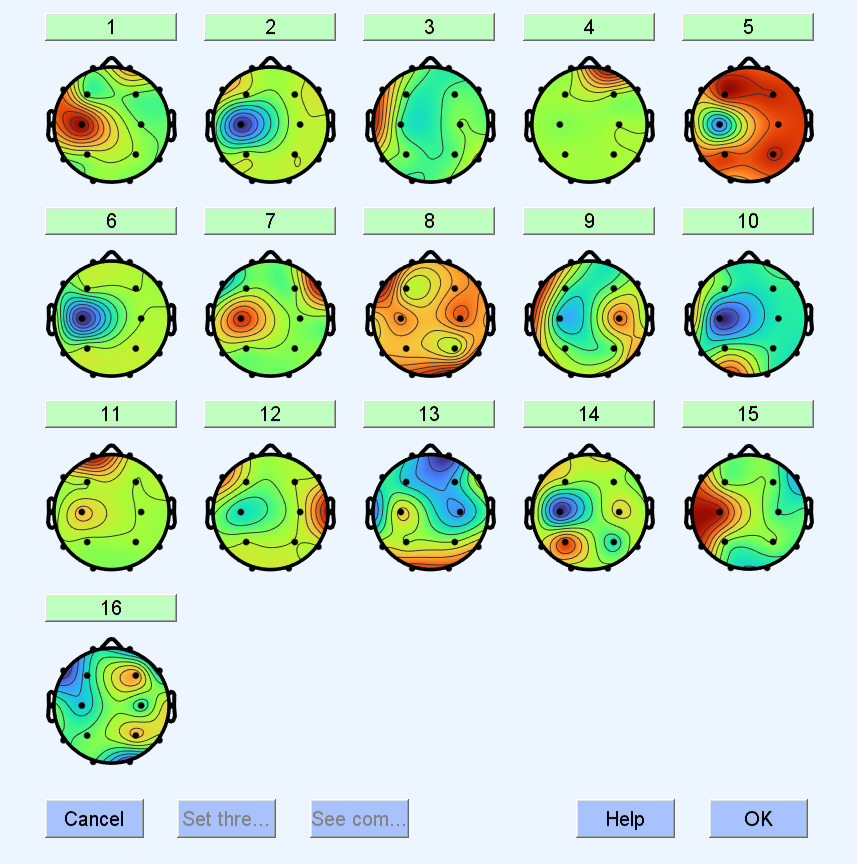

Computing projection and removing 2 components ....
Remove Components complete.



%% ICA 컴포넌트 수동 제거
p = p.removeComponents();


%% 재참조 및 저장
p = p.rereference();

Re-referencing data
Re-referencing ICA matrix
Scaling components to RMS microvolt
Re-referencing complete.



EEG_clean = p.getEEG();
pop_saveset(EEG_clean, 'filename', save_filename, 'filepath', EEG_clean.filepath);

Scaling components to RMS microvolt
Saving dataset...


disp('전처리 완료');

전처리 완료
